# Two Heaters: Dynamic Temperature Modeling

**Objective**: Derive a nonlinear transient model for two heaters and compare the model predictions with the Arduino temperature control lab measurements.

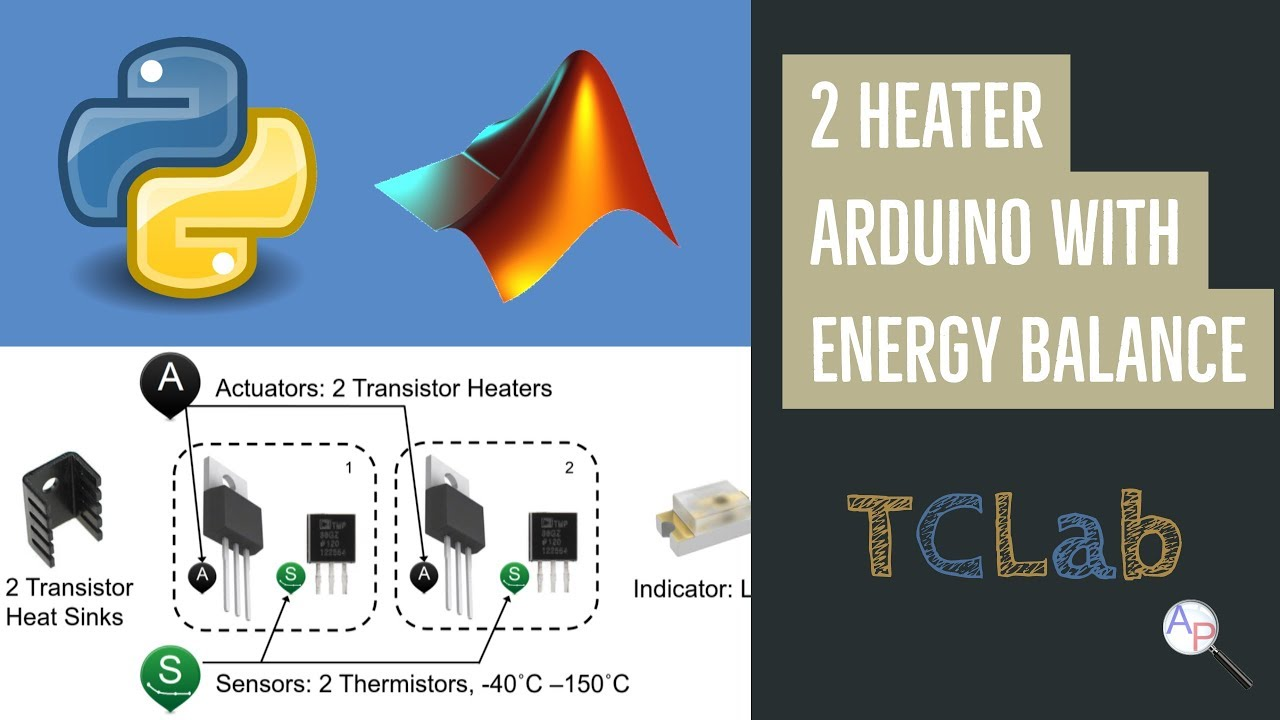

### [View Lecture](https://www.youtube.com/watch?v=SWiLkVJCdfA)

A next step in the modeling, beyond the single heater model, is to develop a dual heater model and add the heat transfer between them. The temperature control lab has two transistor heaters and two temperature sensors as shown in the figure below.

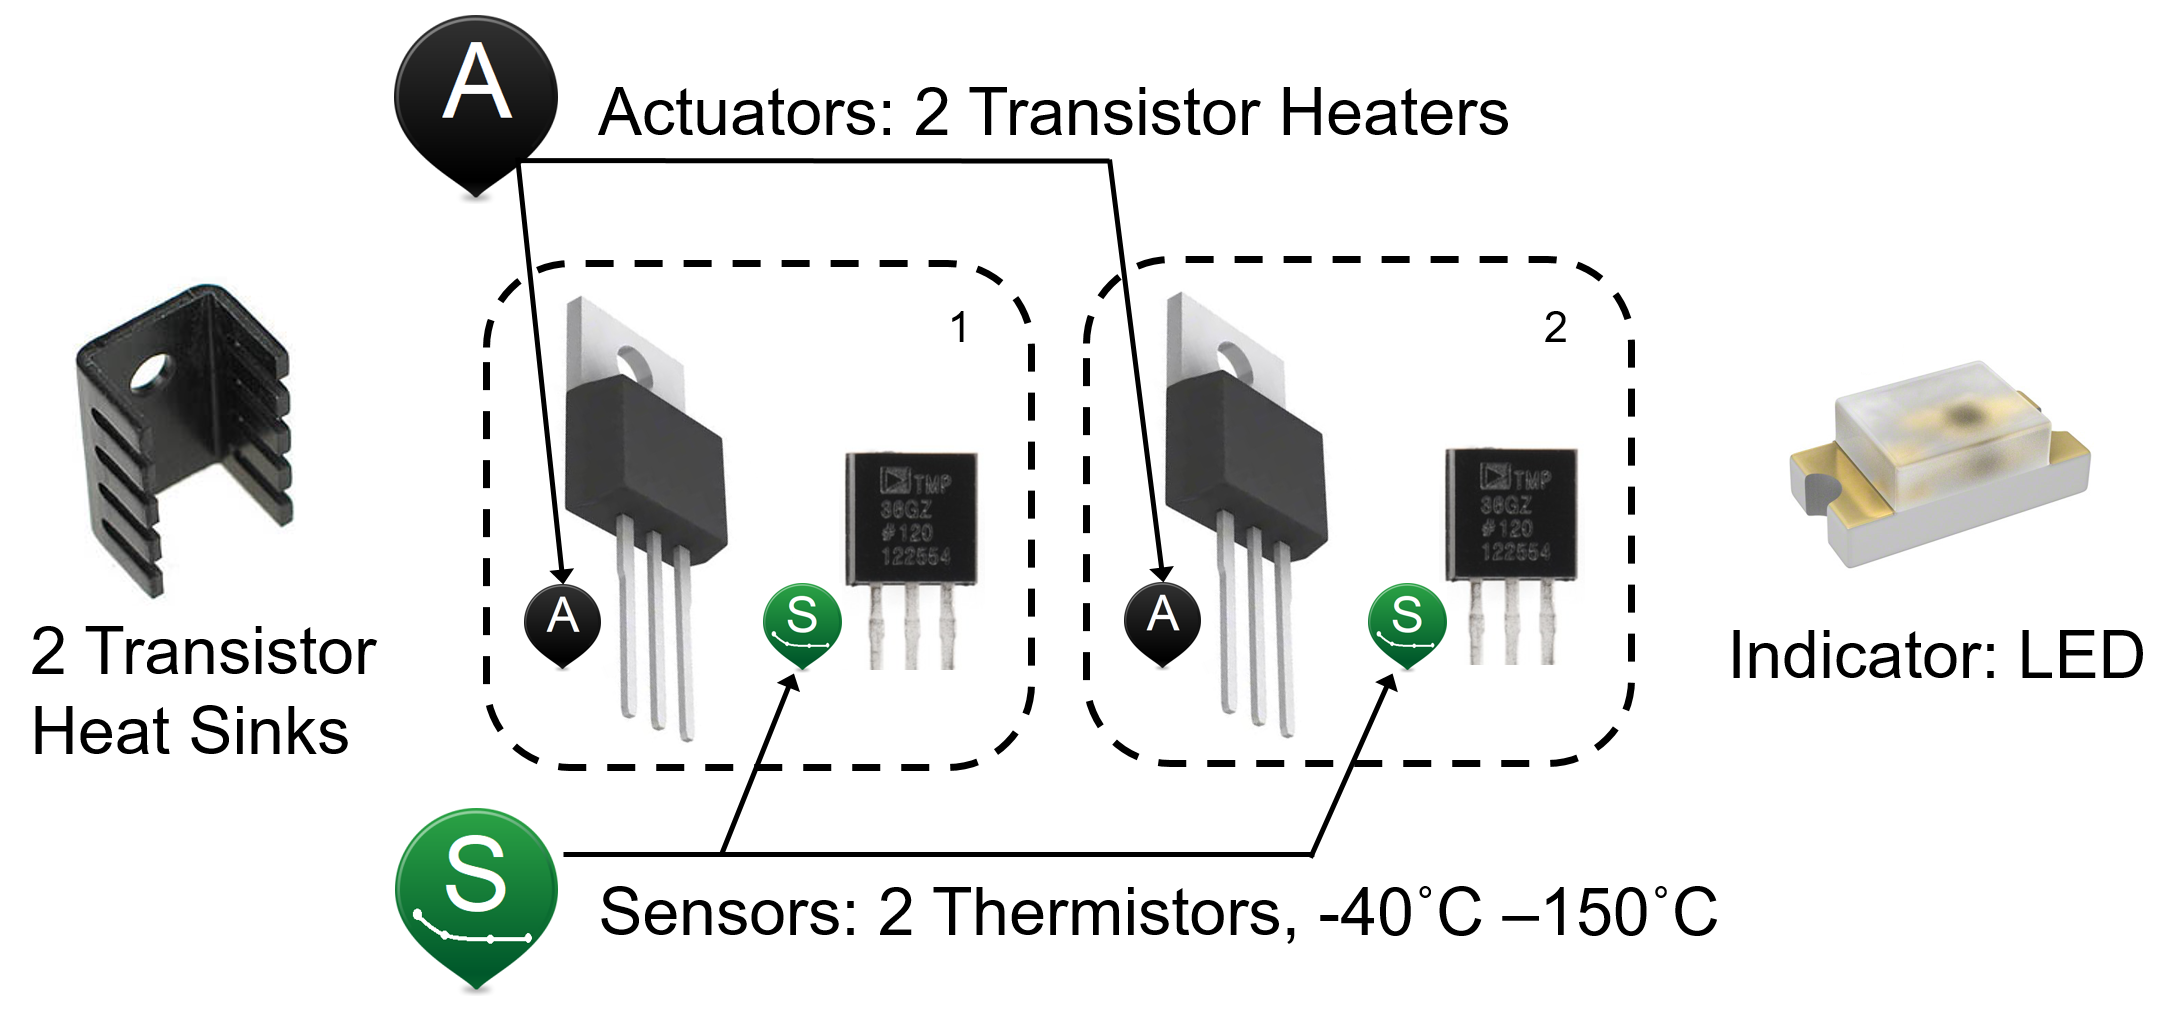

The model for the dual heater system is similar to the single heater model except that the surface is further differentiated for area that is between the two heaters (2 $\text{cm}^2$) and the area that is not coupled between the heaters (10 $\text{cm}^2$). Also, heater 2 dissipates a maximum of 0.75 W while heater 1 dissipates a maximum of 1.0 W.


$$\matrix{

\textbf{Component} & \textbf{Value}\cr
\text{Initial Temperature}(T_0) & 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Ambient Temperature}(T_\infty)& 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Heater 1 Output}(Q_1) & 0-100\%\cr
\text{Heater 1 Factor}(\alpha_1) & 0.0123 \text{ W/(\% heater)}\cr
\text{Heater 2 Output}(Q_2) & 0-100\%\cr
\text{Heater 2 Factor}(\alpha_2) & 0.0062 \text{ W/(\% heater)}\cr
\text{Heat Capacity}(C_p) & 500 \text{ J/kg-K}\cr
\text{Surface Area Not Between Heaters}(A) & 1.0*10^{-3}\text{ m}^2(10\text{ cm})\cr
\text{Surface Area Between Heaters}(A_s) & 2.0*10^{-4}\text{ m}^2(2\text{ cm})\cr
\text{Mass}(m) & 0.004\text{ kg }(4 \text{ gm })\cr
\text{Conduction Time Constant}(\tau) & 20.3 \text{ sec}\cr
\text{Overall Heat Transfer Coefficient} (U) & 4.7 \text{ W/m}^2\text{-K}\cr
\text{Overall Heat Transfer Coefficient Between Heaters}(U_s) & 15.45 \text{ W/m}^2\text{-K}\cr
\text{Emissivity}(\epsilon) & 0.9\cr
\text{Stefan Boltzmann Constant }(\sigma) & 5.67*10^{-8} \text{ W/m}^2\text{-K}^4\cr
}$$


Create a dynamic model of the dynamic response between the input power to each transistor and the temperature sensed by each thermistor. The model is similar to the energy balance model for a single heater but now includes convective and radiative heat transfer between the two heating elements.


$$Q_{C12} = U \, A_s \, \left(T_2-T_1\right)$$



$$Q_{R12} = \epsilon\,\sigma\,A\,\left(T_2^4-T_1^4\right)$$


Two energy balance equations describe the dynamic temperature response of the two temperature sensors given the heater inputs.


$$m\,c_p\frac{dT_1}{dt} = U\,A\,\left(T_\infty-T_1\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_1^4\right) + Q_{C12} + Q_{R12} + \alpha_1 Q_1$$



$$m\,c_p\frac{dT_2}{dt} = U\,A\,\left(T_\infty-T_2\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_2^4\right) - Q_{C12} - Q_{R12} + \alpha_2 Q_2$$


Use these equations to develop a dynamic simulation of the temperature response due to an impulse (off, on, off) in the heater outputs. Leave the heater on for sufficient time to observe nearly steady state conditions.

## Dual Heater Model

clear all; close all; clc

n = 60*10+1;  % Number of second time points (10min)

% Percent Heater (0-100%)
Q1 = zeros(n,1);
Q2 = zeros(n,1);
% Heater steps
Q1(7:end) = 100.0;   % at 0.1 min (6 sec)
Q2(301:end) = 100.0; % at 5.0 min (300 sec)

% Initial temperature
T0 = 23.0 + 273.15;

% Store temperature results
T1 = ones(n,1)*T0;
T2 = ones(n,1)*T0;

time = linspace(0,n-1,n); % Time vector

for i = 2:n
    % initial condition for next step
    x0 = [T1(i-1),T2(i-1)];
    % time interval for next step
    tm = [time(i-1),time(i)];
    % Integrate ODE for 1 sec each loop
    z = ode45(@(t,x)heat2(t,x,Q1(i-1),Q2(i-1)),tm,x0);
    % record T1 and T2 at end of simulation
    T1(i) = z.y(1,end);
    T2(i) = z.y(2,end);
end

% Plot results
figure(1)

subplot(2,1,1)
plot(time/60.0,T1-273.15,'b-','LineWidth',2)
hold on
plot(time/60.0,T2-273.15,'r--','LineWidth',2)
ylabel('Temperature (degC)')
legend('T_1','T_2')

subplot(2,1,2)
plot(time/60.0,Q1,'b-','LineWidth',2)
hold on
plot(time/60.0,Q2,'r--','LineWidth',2)
ylabel('Heater Output')
legend('Q_1','Q_2')
ylim([-10,110])
xlabel('Time (min)')

Investigate issues such as whether radiative heat transfer is significant, is the temperature response inherently first order or higher order, and what values of uncertain parameters in the physics based model help the predicted temperature agree with the data.

## **Dual Heater Model + Arduino**

Test the agreement of the model with the Arduino temperature control lab. Report the cumulative error and the average error over 10 minutes with a step test for heater 1 at 10 seconds and heater 2 at 5 minutes.

### MATLAB

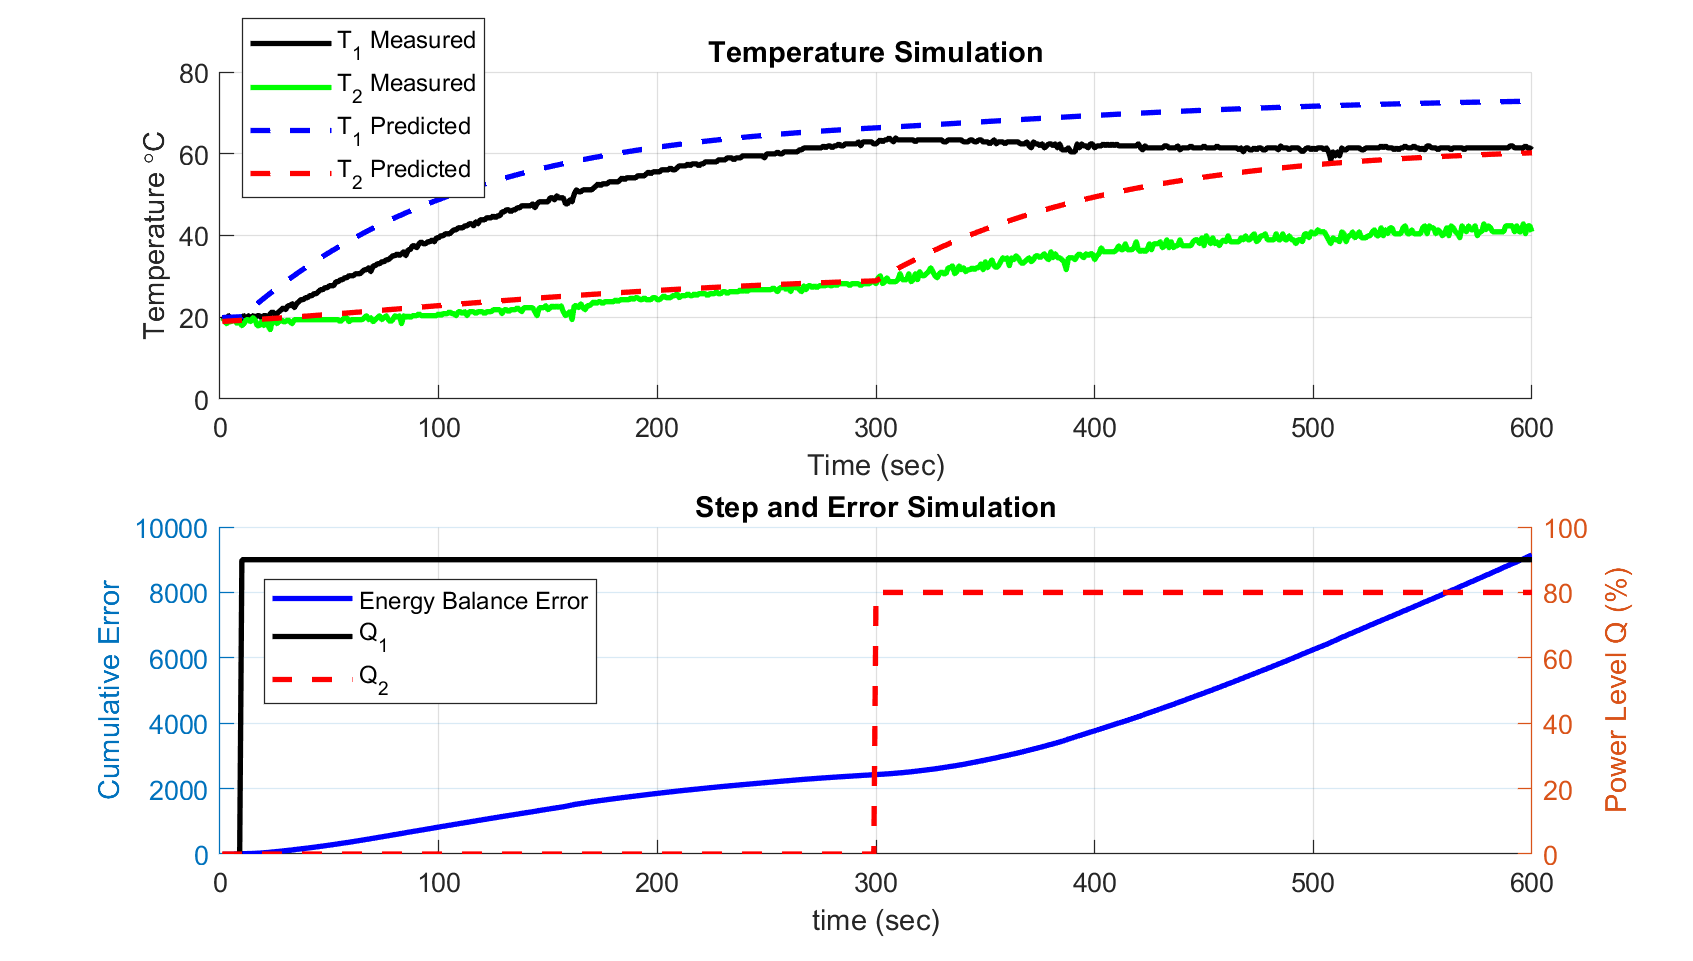

  [**Download MATLAB TCLab Files for Dual Heaters**](https://apmonitor.com/pdc/uploads/Main/tclab_matlab_mimo.zip)

clc; clear all; close all;

lab = tclab;

% simulation time
time = 10;           % time in min
loops = time*60;        % simulation time in seconds

% Measurements and Predictions
time = zeros(1,loops);
T1 = ones(1,loops) * lab.T1();       % measured T (sensor 1)
T2 = ones(1,loops) * lab.T2();       % measured T (sensor 2)
Tp1 = ones(1,loops) * lab.T1();      % pred T1 (energy balance model)
Tp2 = ones(1,loops) * lab.T2();      % pred T2 (energy balance model)

% Error & Power allocation
error1 = zeros(loops,1);         % error vector for T1 model
error2 = zeros(loops,1);         % error vector for T2 model
Q = zeros(loops,2);
% adjust heater levels
Q(10:end,1) = 90;   % heater 1
Q(300:end,2) = 80;  % heater 2

start_time = clock;
prev_time = start_time;

% dynamic plot (note: subplots needs to be declared here first)
figure(1)
subplot(2,1,1)
hold on, grid on
anexp1 = animatedline('LineStyle','-', 'Color', 'k', 'LineWidth', 2);
anexp2 = animatedline('LineStyle','-', 'Color', 'g', 'LineWidth', 2);
anpred1 = animatedline('LineStyle','--','Color', 'b','LineWidth', 2);
anpred2 = animatedline('LineStyle','--','Color', 'r', 'LineWidth', 2);
xlabel('Time (sec)')
ylabel('Temperature \circC')
legend('T_1 Measured', 'T_2 Measured', ...
    'T_1 Predicted', 'T_2 Predicted', ...
    'Location', 'northwest')
title('Temperature Simulation')
subplot(2,1,2)
hold on, grid on
yyaxis left
anerror = animatedline('LineStyle','-', 'Color', 'b', 'LineWidth', 2);
xlabel('Time (sec)')
ylabel('Cumulative Error')
yyaxis right
title('Step and Error Simulation')
anQ1 = animatedline('LineStyle','-', 'Color', 'k', 'LineWidth', 2);
anQ2 = animatedline('LineStyle','--', 'Color', 'r', 'LineWidth', 2);
ylabel('Power Level Q (%)')
xlabel('time (sec)')
legend('Energy Balance Error', 'Q_1', 'Q_2', 'Location', 'northwest')

for ii = 1:loops
    % adjust power level
    Q1s(ii) = Q(ii,1);
    Q2s(ii) = Q(ii,2);
    lab.Q1(Q1s(ii));
    lab.Q2(Q2s(ii));
    
    % Pause Sleep time
    pause_max = 1.0;
    pause_time = pause_max - etime(clock,prev_time);
    if pause_time >= 0.0
        pause(pause_time - 0.01)
    else
        pause(0.01)
    end
    
    % Record time and change in time
    t = clock;
    dt = etime(t,prev_time);
    if ii>=2
        time(ii) = time(ii-1) + dt;
    end
    prev_time = t;
    
    % non-linear energy balance
    jj = ii+1;
    [tsim, Tnext_fnd] = ode45(@(tsim,x)heat2(tsim,x,...
        Q1s(ii),Q2s(ii)), [0 dt],...
        [Tp1(jj-1)+273.15,Tp2(jj-1)+273.15]);
    Tp1(jj) = Tnext_fnd(end,1) - 273.15;
    Tp2(jj) = Tnext_fnd(end,2) - 273.15;
        
    % read and record from temperature controller
    T1(ii) = lab.T1;
    T2(ii) = lab.T2;
    
    % calculate error
    error1(jj) = error1(ii) + dt * abs(T1(ii) - Tp1(ii));
    error2(jj) = error2(ii) + dt * abs(T2(ii) - Tp2(ii));
    error(jj) = error1(jj) + error2(jj);
    
    % plot
    addpoints(anexp1,time(ii),T1(ii))
    addpoints(anexp2,time(ii),T2(ii))
    addpoints(anpred1,time(ii),Tp1(ii))
    addpoints(anpred2,time(ii),Tp2(ii))
    addpoints(anerror,time(ii),error(ii))
    addpoints(anQ1,time(ii),Q1s(ii))
    addpoints(anQ2,time(ii),Q2s(ii))
    drawnow
    
end

disp(['Energy Balance Cumulative Error =', num2str(error(end,1))]);
lab.Q1(0);
lab.Q2(0);
disp('Heaters off')
% turn off heater but keep LED on if T > 50
if (lab.T1 || lab.T2) > 50
    led(1)
    disp(['Warning, heater temperature 1 =', num2str(T1C())])
    disp(['Warning, heater temperature 2 =', num2str(T2C())])
else
    led(0)
end

% save txt file with data
data = [time',Q1s',Q2s',T1',T2'];
csvwrite('data.txt',data);

### Simulink

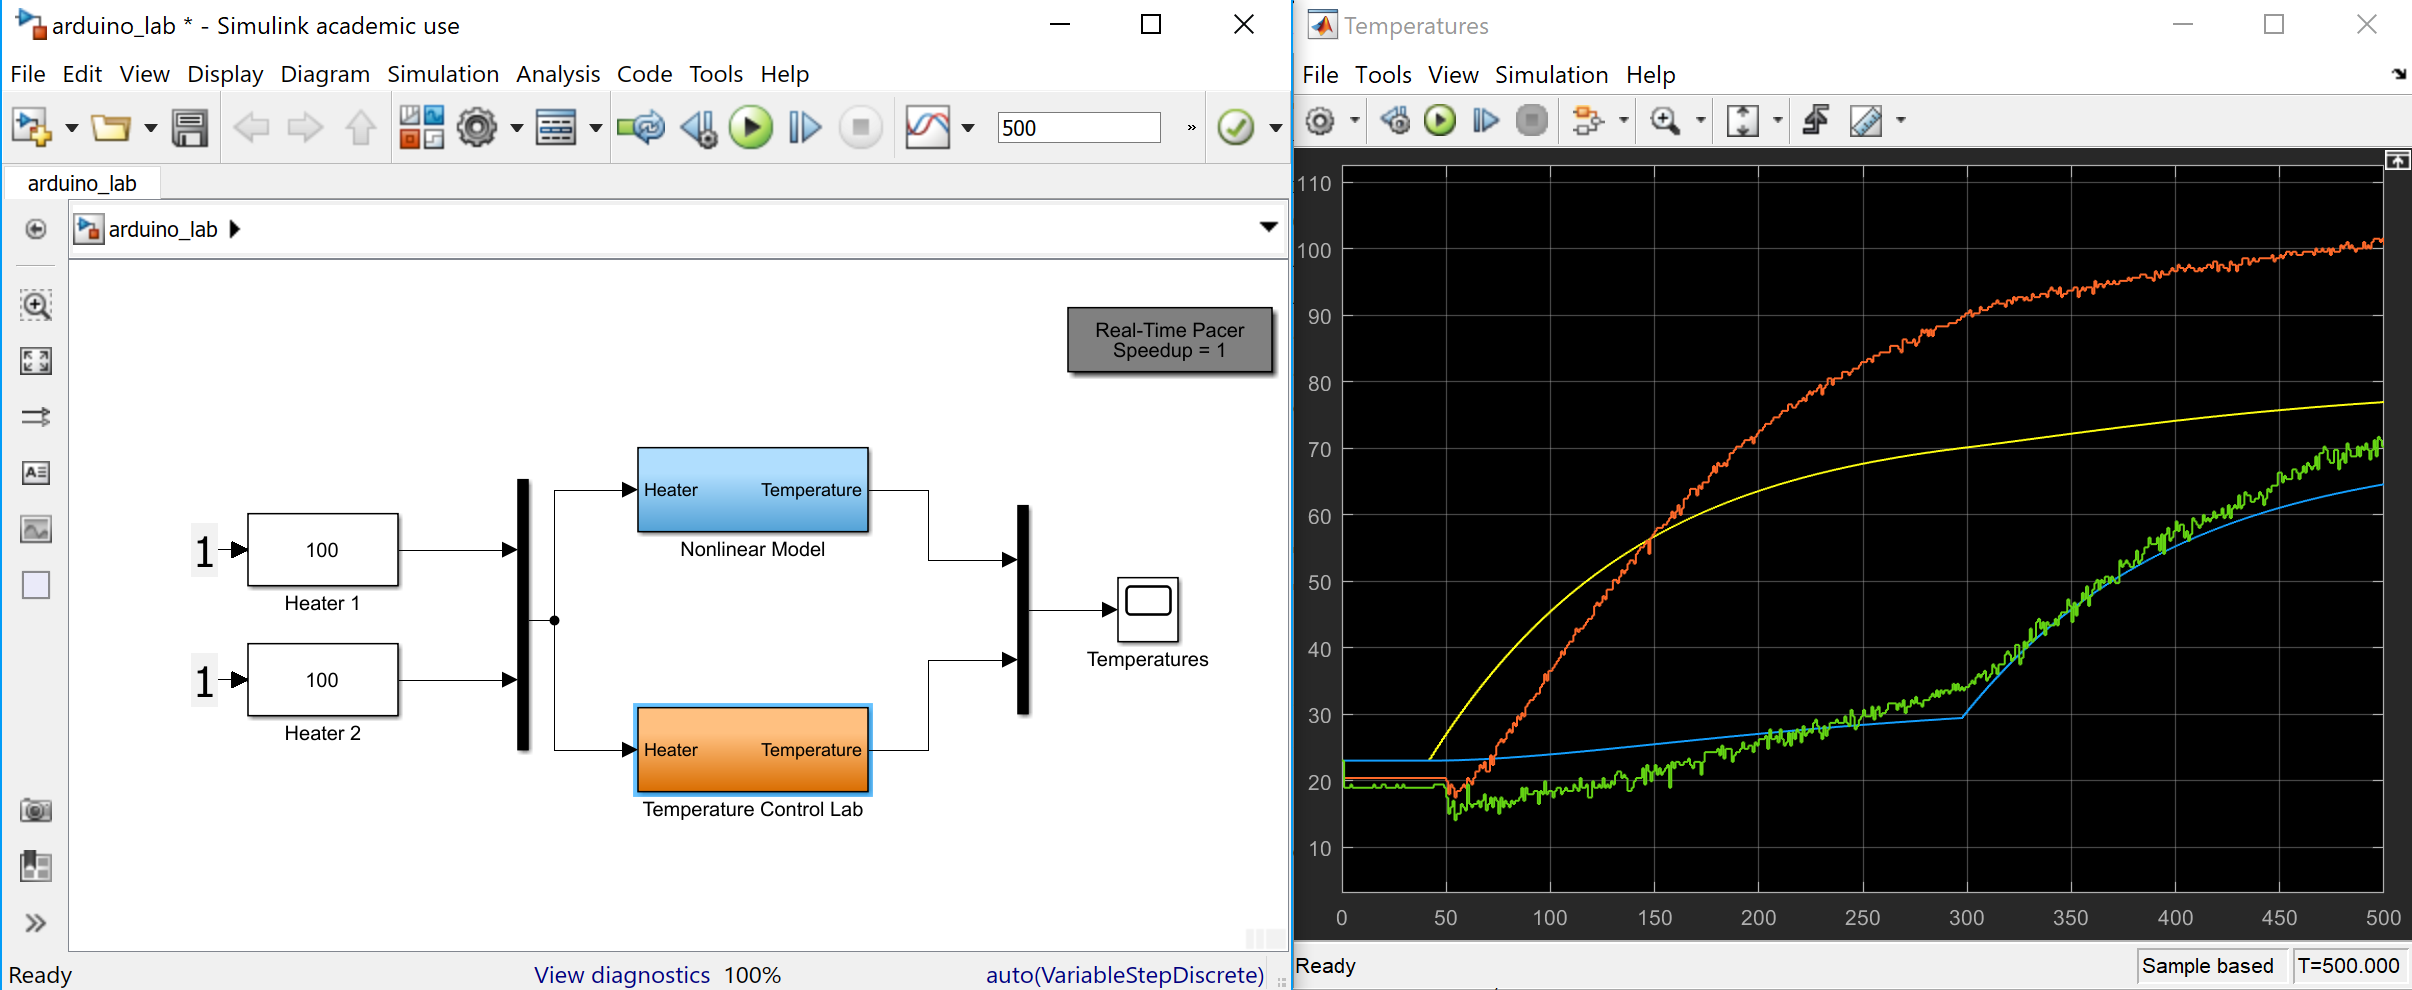

 [**Download Simulink TCLab Files for Dual Heaters**](https://apmonitor.com/pdc/uploads/Main/tclab_simulink_mimo.zip)

function dTdt = heat2(~,x,Q1,Q2)
    % Parameters
    Ta = 23 + 273.15;   % K
    U = 10.0;           % W/m^2-K
    m = 4.0/1000.0;     % kg
    Cp = 0.5 * 1000.0;  % J/kg-K    
    A = 10.0 / 100.0^2; % Area in m^2
    As = 2.0 / 100.0^2; % Area in m^2
    alpha1 = 0.0100;    % W / % heater 1
    alpha2 = 0.0075;    % W / % heater 2
    eps = 0.9;          % Emissivity
    sigma = 5.67e-8;    % Stefan-Boltzman

    % Temperature States
    T1 = x(1);
    T2 = x(2);

    % Heat Transfer Exchange Between 1 and 2
    conv12 = U*As*(T2-T1);
    rad12  = eps*sigma*As * (T2^4 - T1^4);

    % Nonlinear Energy Balances
    dT1dt = (1.0/(m*Cp))*(U*A*(Ta-T1) ...
            + eps * sigma * A * (Ta^4 - T1^4) ...
            + conv12 + rad12 ...
            + alpha1*Q1);
    dT2dt = (1.0/(m*Cp))*(U*A*(Ta-T2) ...
            + eps * sigma * A * (Ta^4 - T2^4) ...
            - conv12 - rad12 ...
            + alpha2*Q2);
    dTdt = [dT1dt,dT2dt]';
end